% Main Code
% Sirio: sirio.belga_fedeli@kcl.ac.uk

% Parallel Computing
% Uncomment the following 2 lines for more machines
%delete(gcp('nocreate'));
%parpool('local');

% split in function the following blocks
clear all;

## Onset Conditions

dimension:

N=50;
% correlation paramter:
eta=1.;
% amplitude
JAmp=1;
% Sparsity of J
Mdensity=0;
% Number of time steps:
N_tot=1000000;
% Delta t:
Dt=0.0001;
% Temperature: Increase it!!!
T=0.001;
% Initialise
J=zeros(N,N);
x=zeros(N,N_tot);
% ICs
var_ICs_X=0.01;
x(:,1)=var_ICs_X*randn(N,1);
M=sum(x(:,1).^2);
% Fix the constraint sum x^2=N for all t
x(:,1)=x(:,1)*sqrt(N)/sqrt(M);

## Generate Random Matrix:

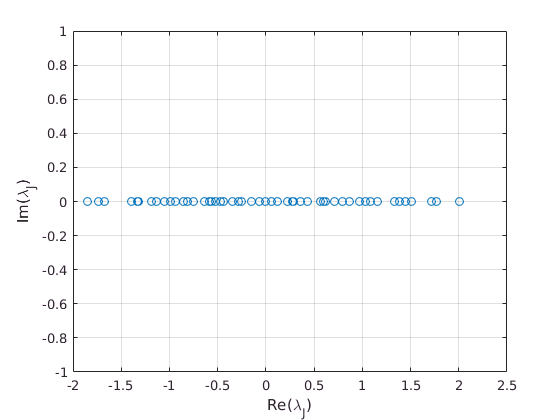

if eta==0
    J=JAmp/sqrt(N)*randn(N);   
 % In case you want sparse:  
 % J=JAmp/sqrt(n)*sprandn(n,n,Mdensity);
J=J-diag(diag(J));
else
    a=sqrt(1-eta^2);
    a=sqrt((1-a)/2);
    b=eta/(2*a);    
    J=JAmp/sqrt(N)*randn(N);    
 % In case you want sparse:  
 % J=JAmp/sqrt(n)*sprandn(n,n,Mdensity);
    J=a*J+b*J';
    J=J-diag(diag(J));
end;
figure;
plot(real(eig(J)),imag(eig(J)),'o');hold on;grid on;
xlabel('Re(\lambda_J)');
ylabel('Im(\lambda_J)')
hold on;

## Time steps

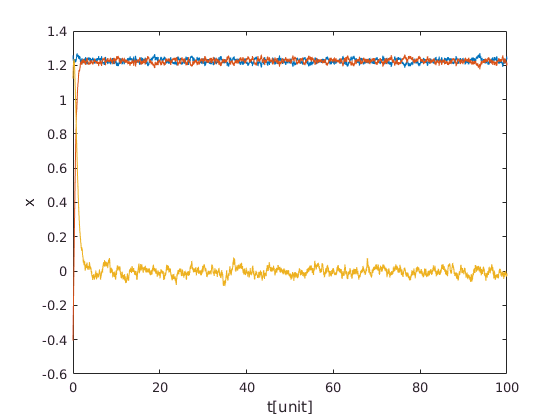

for i=2:N_tot

x(:,i)=x(:,i-1)+Dt*(-x(:,i-1)/N*(x(:,i-1)'*J*x(:,i-1))+J*x(:,i-1))+(eye(N)-1/N*x(:,i-1)*x(:,i-1)')*randn(N,1)*sqrt(2*Dt*T);

end;

% alternative Intermediate update: splitting method-

figure;
% Take into account the transient
plot((0:N_tot-1)*Dt,x); hold on;
xlabel('t[unit]');
ylabel('x');

## Evolution of the constraint sum x^2=N

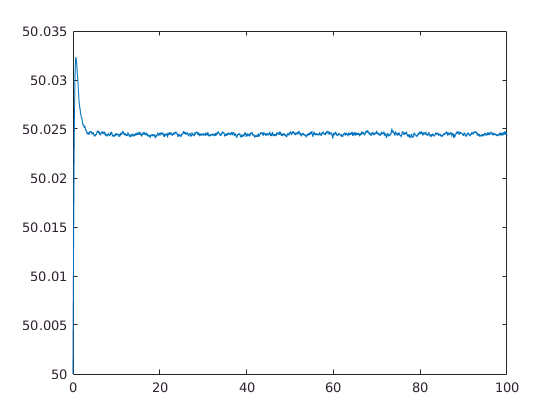

%for i=1:N_tot
%C(i)=x(:,i)'*x(:,i);
%end;
% I believe that this would be faster
C=sum(x.^2,1);

figure;
plot((0:N_tot-1)*Dt,C);

**Projection on the eigenvector correspoding to the highest eigenvalue**

[V,D,W]=eig(J);
[hst_eigvalue,pos]=max(diag(D));
hst_eigvect=V(:,pos)

hst_eigvect =     0.1804
   -0.0026
   -0.1232
   -0.0510
    0.1118
   -0.0197
   -0.0760
    0.0298
   -0.1727
    0.1336


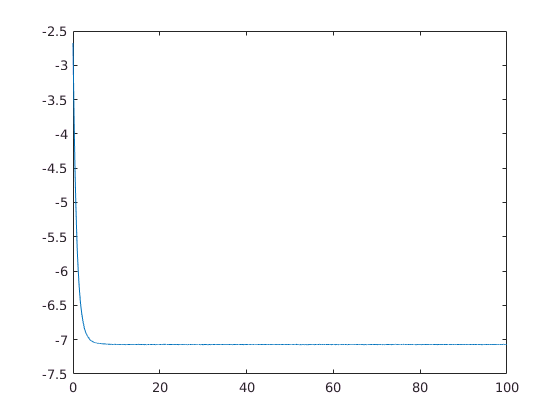

plot((0:N_tot-1)*Dt,x'*hst_eigvect)

sqrt(N)

ans = 7.0711